# **ASL American Sign Language Detection using Bayesian Networks and Convolutional Neural Networks**

## Course “Advanced Data Analysis and Machine Learning”

### **Project work 2**

### Authors: 

#### Thanh Tran (000285359)

#### Nghia Nguyen (000275466)

#### Swapnil Baad (000323486)

Report can be accessed with read-only priviledge from [Group_ASL_A2_report.docx](https://lut-my.sharepoint.com/:w:/g/personal/thanh_tran_student_lut_fi/ERNxVSaZ6XhNpJh_Ecmp26oBOtcaGtWC5TtH-ybKX2-_Uw?e=hczf4M)

## SETUP

temp = true;
Data_loading = true;
Feature_extraction_1_example = false;
Feature_extraction_1_actual = false;
Feature_extraction_2_example = false;
Feature_extraction_2_actual = false;

## IMPORT DATA

if Data_loading
    % Define environment variables
    class_list = {"K", "L", "M", "N", "O", "P", "Q", "R", "S", "T"};                                    % All classes included in this project
    nClass = length(class_list);                                                                        % The number of classes included
    train_data_path = "./data/asl_alphabet_train/asl_alphabet_train";                                  % File path to the directory of train data
    test_data_path = "./data/asl_alphabet_test/asl_alphabet_test";                                     % File path to the directory of test data
    
    % Load images and convert to RGB data matrices
    Xtemplates_filename = {};
    Ytemplates = [];
    Xtrain = {};
    Ytrain = [];
    nSamplePerClass = zeros(nClass, 1);
    disp('Data loading ...');
    for c = 1:nClass    
        class_dir = sprintf(train_data_path + "/" + class_list{c});
        file_list = dir(class_dir);
        file_list = file_list(3:end);
        nImage = length(file_list);
        nSamplePerClass(c) = nImage;
        for i = 1:nImage
            path_to_image = sprintf(class_dir + "/" + file_list(i).name);
            image_RGB = imread(path_to_image);
            image_gray = rgb2gray(image_RGB);
            Xtrain{end+1} = image_gray;
            Ytrain = [Ytrain, class_list{c}];
            
            % Get one every 100 images per class and save as templates of class
            if ismember(i, 1:100:nImage)
                Xtemplates_filename{end+1} = path_to_image;
                Ytemplates = [Ytemplates, class_list{c}];
            end
    
        end
    
        fprintf('   Class %s loading done.\n', class_list{c});
    end
    save extracted_features\templates.mat Xtemplates_filename Ytemplates

    nXtrain = length(Xtrain);
    Cum_nSamplePerClass = cumsum(nSamplePerClass);
end

Data loading ...


   Class K loading done.
   Class L loading done.
   Class M loading done.
   Class N loading done.
   Class O loading done.


## FEATURE EXTRACTION

### 1 Hand segmentation and SIFT Feature

#### 1.1 Examples with visualization

if Feature_extraction_1_example && Data_loading
    nExample = 1;
    nExampleClass = 3;
    for c = 1:nExampleClass
        fprintf('Class %s feature extracting example(s):\n', class_list{c});
        sample_idxs = find(Ytrain == class_list{c}, nExample);
        for i = 1:nExample
            SIFT_points = bound_key_region(Xtrain{sample_idxs(i)}, true);
        end
    end
end

#### 1.2 Actual Extraction

if Feature_extraction_1_actual && Data_loading
    nSIFTPoints = 5;
    Xtrain_SIFTPoints = zeros(nXtrain, nSIFTPoints*2);
    for i = 1:nXtrain
        SIFT_points = bound_key_region(Xtrain{i});
        Xtrain_SIFTPoints(i,1:length(SIFT_points)) = SIFT_points;
        if ismember(i, Cum_nSamplePerClass)
            fprintf('   Class %s feature extracting done.\n', Ytrain(i));
        end
    end
    
    save extracted_features\Xtrain_SIFTPoints.mat Xtrain_SIFTPoints
end

### 2 Matched SURF Feature count

#### 2.1 Examples with visualization

if Feature_extraction_2_example && Data_loading
    nExample = 1;
    nExampleClass = 3;
    for c = 1:nExampleClass
        fprintf('Class %s feature extracting example(s):\n', class_list{c});
        sample_idxs = find(Ytrain == class_list{c}, nExample);
        for i = 1:nExample
            bestnMatches = get_best_nMatchedFeatures(Xtrain{sample_idxs(i)}, true);
        end
    end
end

#### 2.2 Actual Extraction

%% TO BE DONE TO EXTRACT THE SECOND FEATURES
if Feature_extraction_2_actual && Data_loading
    load extracted_features\templates.mat Xtemplates_filename Ytemplates
    TemplateClasses = unique(Ytemplates);
    nTemplateClasses = length(TemplateClasses);

    Xtrain_nMatchedFeatures = zeros(nXtrain,nTemplateClasses);
    for i = 1:nXtrain
        Xtrain_nMatchedFeatures(i,:) = get_best_nMatchedFeatures(Xtrain{i}, false);
    end
    
    save extracted_features\Xtrain_nMatchedFeatures.mat Xtrain_nMatchedFeatures
end

if temp && Data_loading
    load extracted_features\templates.mat Xtemplates_filename Ytemplates
    TemplateClasses = unique(Ytemplates);
    nTemplateClasses = length(TemplateClasses);

    Xtrain_nMatchedFeatures = zeros(nXtrain,nTemplateClasses);
    for i = 15001:nXtrain
        Xtrain_nMatchedFeatures(i,:) = get_best_nMatchedFeatures(Xtrain{i}, false);
    end
    
    x3 = Xtrain_nMatchedFeatures(15001:nXtrain,:);
    save Xtrain_nMatchedFeaturesQRST.mat x3
end



## 3 Bayesian Network

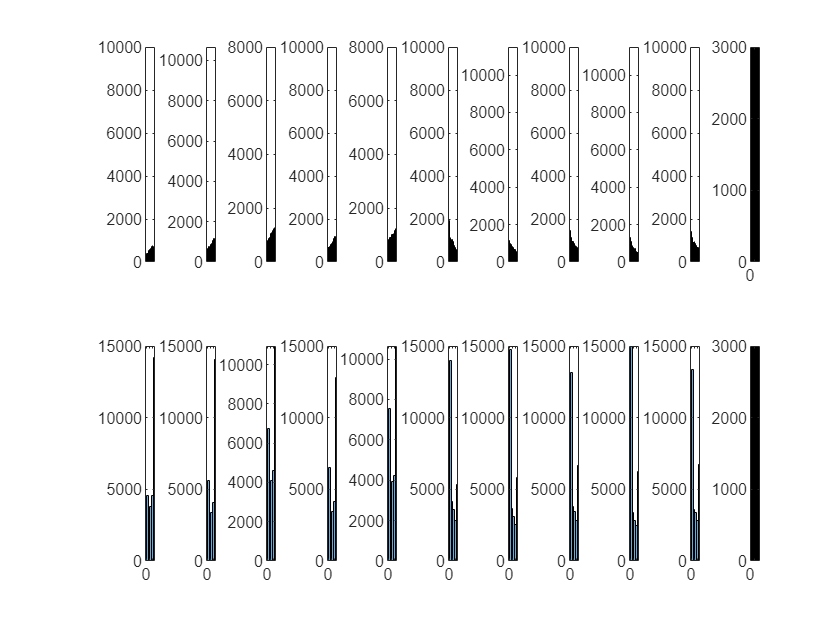

clear;
close all;
load extracted_features\Xtrain_SIFTPoints_table.mat
load extracted_features\Ytrain.mat
Xtrain_extracted = Xtrain_SIFTPoints_table;


% USE VARIABLE NAMED Xtrain_extracted AS TRAINING AND VALIDATING DATA
[nXtrain, nCol] = size(Xtrain_extracted);
varLabels = ["SP1x", "SP1y", "SP2x", "SP2y", "SP3x", "SP3y", "SP4x", "SP4y", "SP5x", "SP5y","Label"];

% discretization

nseg = 5;
X_train = table2array(Xtrain_extracted);
X_train(:,end+1) = grp2idx(categorical(Ytrain));

for i = 1:length(X_train(1,1:end-1))

    var     = X_train(:,i);

    minVal  = min(var);
    maxVar  = max(var);

    segLength = maxVar - minVal;
    subSegLength = segLength/nseg;

    seg(1).LB = minVal;

    for ii = 1:nseg
        if ii ~= 1
            seg(ii).LB = seg(ii-1).LB + subSegLength + 0.0001;
        end
    end

    for ii = 1:nseg-1
        idxCurrent = intersect(find(X_train(:,i)>=seg(ii).LB), find(X_train(:,i)<seg(ii+1).LB));
        X_train_Descrt(idxCurrent,i) = ii;
    end

    idxCurrent = find(X_train(:,i)>seg(ii+1).LB);
    X_train_Descrt(idxCurrent,i) = ii+1;

end

% Visualizing the data
X_train_Descrt(:,end+1) = X_train(:,end);

[row, col]      = size(X_train_Descrt);
[row2, col2]      = size(X_train);


ii = 1;
for i = 1:col
    col2=i;

    subplot(2, col, i);
    histogram(X_train(:,i));

    subplot(2, col, i+col);
    histogram(X_train_Descrt(:,i)); 
    col2=col2+1;
end

% Partitioning
c       = cvpartition(X_train(:,end), 'Holdout', 0.3);
idxTest = test(c);
idxCal  = training(c);

% % For point 4.2, run the following  commented
% %code with your choice of removed variables
% data2(:, [2 3 4 5 6 7 9 10])  = [];
% varLabels([2 3 4 5 6 7 9 10]) = [];
% [row, col]             = size(data2);

dataAll  = X_train_Descrt;
X_train_Descrt    = [];
X_train_Descrt    = dataAll(idxCal,  :);
dataTest = dataAll(idxTest, :);


%% Modeling
folderPath = 'C:\Users\swapn\Downloads\bnt-master\bnt-master';
addpath(genpath(folderPath))

ncases  = row;
cases   = cell(col, ncases);
cases   = num2cell(X_train_Descrt');

node_sizes = [];
for i = 1:col
    node_sizes = [node_sizes, length(unique(X_train_Descrt(:,i)))];
    variable(i).node = i;
end

DAGhat = learn_struct_K2(cases, node_sizes, [variable.node], ...
    'max_fan_in', 3, 'verbose', 'yes');


node 1, empty score -29647.8193

node 2, empty score -29468.4886
considering adding 1 to 2, score -27871.4581
* adding 1 to 2, score -27871.4581

node 3, empty score -31809.6298
considering adding 1 to 3, score -31143.3486
considering adding 2 to 3, score -30912.5852
* adding 2 to 3, score -30912.5852
considering adding 1 to 3, score -31019.5511

node 4, empty score -30397.2235
considering adding 1 to 4, score -29505.1347
considering adding 2 to 4, score -29615.8292
considering adding 3 to 4, score -29483.8800
* adding 3 to 4, score -29483.8800
considering adding 1 to 4, score -29333.9735
considering adding 2 to 4, score -29382.4830
* adding 1 to 4, score -29333.9735
considering adding 2 to 4, score -31654.9124

node 5, empty score -31743.5821
considering adding 1 to 5, score -31365.0628
considering adding 2 to 5, score -31288.2073
considering adding 3 to 5, score -31415.2450
considering adding 4 to 5, score -30922.2990
* adding 4 to 5, score -30922.2990
considering adding 1 to 5, sco

## Bayesian Network Structure

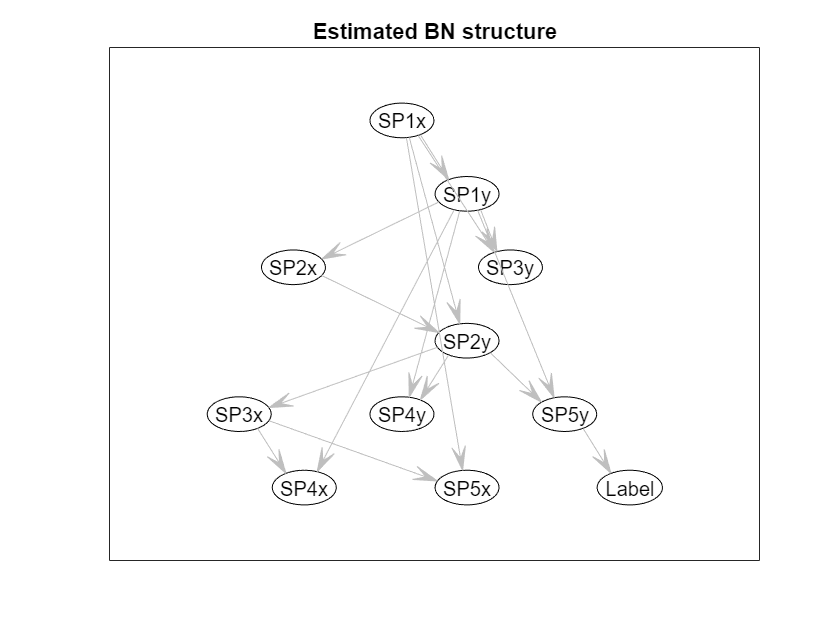

BNtemp = mk_bnet(DAGhat, node_sizes);

for i = 1:col
    BNtemp.CPD{variable(i).node} = tabular_CPD(BNtemp, variable(i).node);
end

BNhat = learn_params(BNtemp, cases);

CPThat = cell(1, col);
for i = 1:col
    s = struct(BNhat.CPD{i});
    CPThat{i} = s.CPT;
end


figure;
draw_graph(BNhat.dag, varLabels);
title('Estimated BN structure');


%Classification
engine       = global_joint_inf_engine(BNhat);
[rowT, colT] = size(dataTest);


for j = 1:rowT
    evidence     = [];
    evidence     = cell(1,colT);
    
    for i = 1:col-1
       evidence{variable(i).node} = dataTest(j,i);

    end
    [engine, logLikelihood] = enter_evidence(engine, evidence);
    marginal       = marginal_nodes(engine, variable(end).node);
    totProb        = sum(marginal.T(:));
    dataPoint(j).M = marginal.T ./ totProb;
    [~, dataPoint(j).yhat] = max(dataPoint(j).M);
end

Array indices must be positive integers or logical values.

Error in discrete_CPD/convert_to_table (line 14)
T = CPT(index{:});

Error in discrete_CPD/convert_to_pot (line 20)
   T = convert_to_table(CPD, domain, evidence);

Error in 


a = categorical([dataPoint.yhat]');
b = categorical(dataTest(:,end));

p1 = find(a == b, 1, 'first');
p2 = find(a ~= b, 1, 'first');